## Simulation

### Initialize and run simulation

T_a = Token("TokenA", true, 1);
T_b = Token("TokenB");
initialT_bPrice = 1;
totalT_a = 10000000;
totalT_b = 10000000;
freeT_a = 8000000;
freeT_b = 8000000;

walletExpRate = 0.00003;
poolFee = 0.003;
sigma = 0.001;

baseVirtualPool = 100000;
poolRecoveryPeriod = 36;

numberOfIterations = 10000;

sim = AlgorithmicStablecoinSimulation(T_a, T_b, initialT_bPrice, ...
    totalT_a, totalT_b, freeT_a, freeT_b, ...
    baseVirtualPool, poolRecoveryPeriod, ...
    numberOfIterations, walletExpRate, poolFee, sigma);

[P_a, P_b, probA, probB, delta, totalT_aSupply, totalT_bSupply, ...
    freeT_aRes, freeT_bRes] = sim.runSimulation();

### Plot results

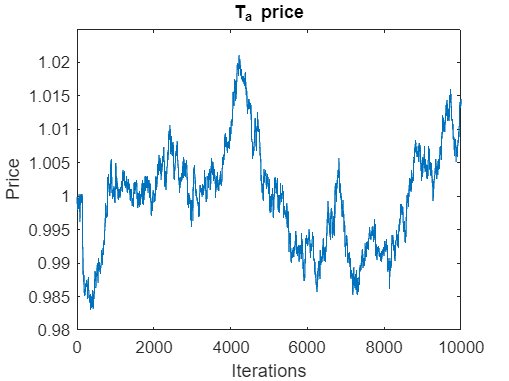

figure;
plot(P_a);
title('T_a price');
xlabel('Iterations');
ylabel('Price');

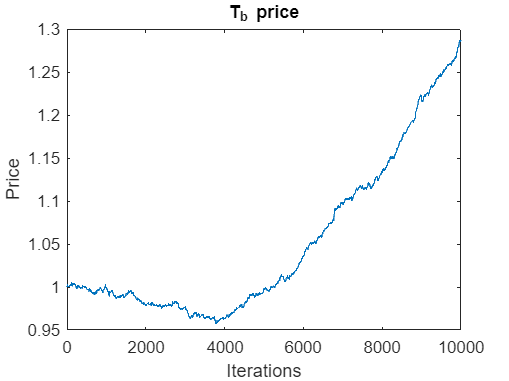

figure;
plot(P_b);
title('T_b price');
xlabel('Iterations');
ylabel('Price');

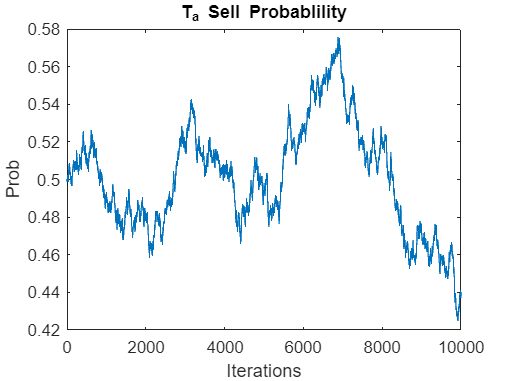


figure;
plot(probA);
title('T_a Sell Probablility');
xlabel('Iterations');
ylabel('Prob');
xlim([0, numberOfIterations]);

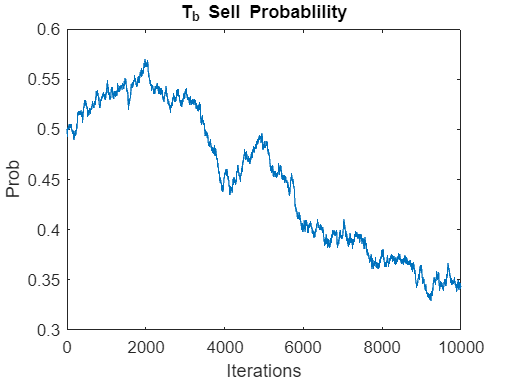

figure;
plot(probB);
title('T_b Sell Probablility');
xlabel('Iterations');
ylabel('Prob');
xlim([0, numberOfIterations]);

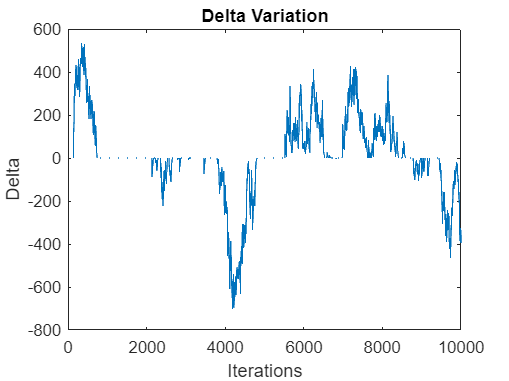


figure;
plot(delta);
title('Delta Variation');
xlabel('Iterations');
ylabel('Delta');
xlim([0, numberOfIterations]);

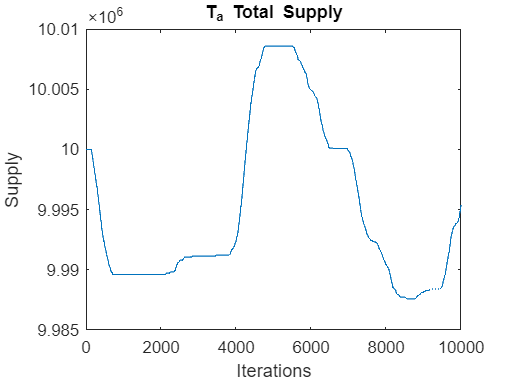


figure;
plot(totalT_aSupply);
title('T_a Total Supply');
xlabel('Iterations');
ylabel('Supply');
xlim([0, numberOfIterations]);

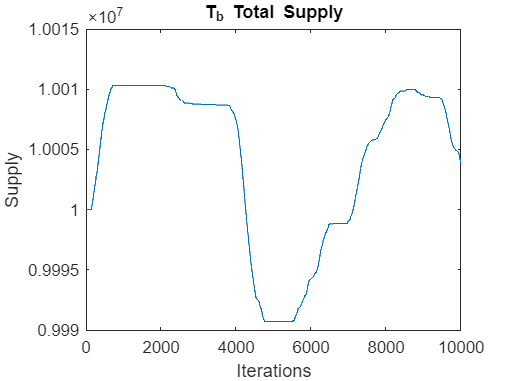

figure;
plot(totalT_bSupply);
title('T_b Total Supply');
xlabel('Iterations');
ylabel('Supply');
xlim([0, numberOfIterations]);

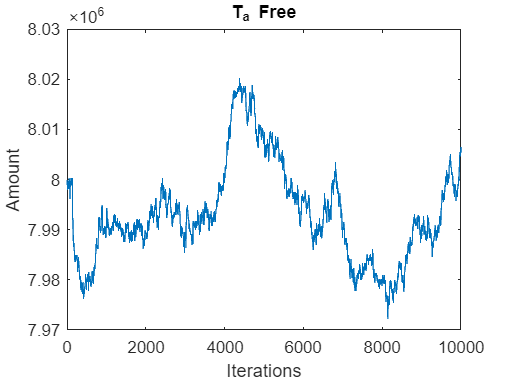


figure;
plot(freeT_aRes);
title('T_a Free');
xlabel('Iterations');
ylabel('Amount');
xlim([0, numberOfIterations]);

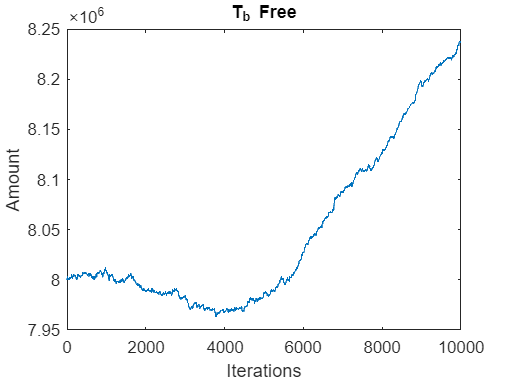

figure;
plot(freeT_bRes);
title('T_b Free');
xlabel('Iterations');
ylabel('Amount');
xlim([0, numberOfIterations]);